# TD 6: Exercice 3 - Opération de convolution

close all;
clearvars;
syms u t a b

sig1= @(t) rectangularPulse(a,b,t)

sig1 = function_handle with value:
    @(t)rectangularPulse(a,b,t)


## On cherche : $y\left (t \right )=x\left ( t \right )*x\left ( t \right )$

## 
$$y\left (t \right )=\int_{-\infty}^{+\infty}x\left ( \tau \right )x\left ( t- \tau \right )d\tau$$


## Avec le retournement de h(t)

x(t)=sig1(t) 

$$x(t) = \mathrm{rectangularPulse}\left(a,b,t\right)$$

h(t)=sig1(t)

$$h(t) = \mathrm{rectangularPulse}\left(a,b,t\right)$$

hc(t)=h(u-t)

$$hc(t) = \mathrm{rectangularPulse}\left(a,b,u-t\right)$$

disp('Expression litterale de y(t)=x(t)*h(t)')

Expression litterale de y(t)=x(t)*h(t)


y1= int(x*hc, t, -inf,+inf)

$$y1 = 2\,\mathrm{heaviside}\left(u-b-a\right)\,\left(a+b-u\right)-\mathrm{heaviside}\left(u-2\,a\right)\,\left(2\,a-u\right)-\mathrm{heaviside}\left(u-2\,b\right)\,\left(2\,b-u\right)$$

Assignation de valeurs pour RC et a pour le tracé de la convolution


aval=0 

aval = 0

bval=2

bval = 2

hp=subs(h,[a, b],[aval, bval])

$$hp(t) = \mathrm{rectangularPulse}\left(0,2,t\right)$$

xp=subs(x,[a, b],[aval, bval])

$$xp(t) = \mathrm{rectangularPulse}\left(0,2,t\right)$$

yp=subs(y1,[a, b],[aval, bval])

$$yp = \mathrm{heaviside}\left(u-4\right)\,\left(u-4\right)-2\,\mathrm{heaviside}\left(u-2\right)\,\left(u-2\right)+u\,\mathrm{heaviside}\left(u\right)$$


figure;
tiledlayout(3,1)
nexttile;
fplot(xp,'b','LineWidth',2)
ylim([-0.1 1.1]);
xmax=2*(bval-aval)+0.1

xmax = 4.1000

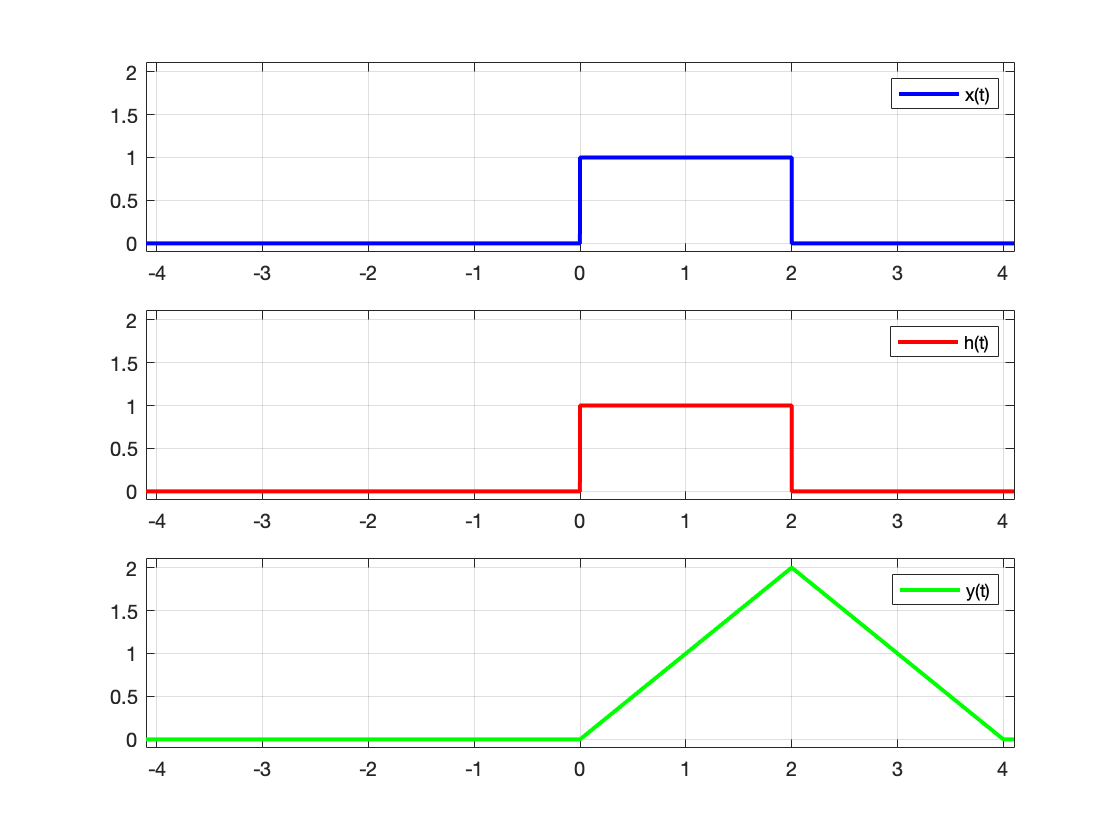

ylim([-0.1 (bval-aval)+0.1]);
xlim([-xmax xmax])
legend('x(t)');
grid on;

nexttile;
fplot(hp,'r','LineWidth',2)
grid on;
legend('h(t)');
ylim([-0.1 (bval-aval)+0.1]);
xlim([-xmax xmax])


nexttile;
fplot(yp,'g','LineWidth',2)
grid on;
legend('y(t)');
ylim([-0.1 (bval-aval)+0.1]);
xlim([-xmax xmax])

## 
$$y\left (t \right )=\int_{-\infty}^{+\infty}x\left ( \tau \right )x\left ( t- \tau \right )d\tau$$


## Avec le retournement de x(t)

x(t)=sig1(t) 

$$x(t) = \mathrm{rectangularPulse}\left(a,b,t\right)$$

h(t)=sig1(t)

$$h(t) = \mathrm{rectangularPulse}\left(a,b,t\right)$$

xc(t)=x(u-t)

$$xc(t) = \mathrm{rectangularPulse}\left(a,b,u-t\right)$$

disp('Expression litterale de y(t)=x(t)*h(t)')

Expression litterale de y(t)=x(t)*h(t)


y2= int(h*xc, t, -inf,+inf)

$$y2 = 2\,\mathrm{heaviside}\left(u-b-a\right)\,\left(a+b-u\right)-\mathrm{heaviside}\left(u-2\,a\right)\,\left(2\,a-u\right)-\mathrm{heaviside}\left(u-2\,b\right)\,\left(2\,b-u\right)$$

Assignation de valeurs pour a et b pour le tracé de la convolution


% aval=-1 
% bval=1
hp=subs(h,[a, b],[aval, bval])

$$hp(t) = \mathrm{rectangularPulse}\left(0,2,t\right)$$

xp=subs(x,[a, b],[aval, bval])

$$xp(t) = \mathrm{rectangularPulse}\left(0,2,t\right)$$

yp=subs(y2,[a, b],[aval, bval])

$$yp = \mathrm{heaviside}\left(u-4\right)\,\left(u-4\right)-2\,\mathrm{heaviside}\left(u-2\right)\,\left(u-2\right)+u\,\mathrm{heaviside}\left(u\right)$$


figure;
tiledlayout(3,1)
nexttile;
fplot(xp,'b','LineWidth',2)
xmax=2*(bval-aval)+0.1

xmax = 4.1000

ylim([-0.1 (bval-aval)+0.1]);
xlim([-xmax xmax])

legend('x(t)');
grid on;

nexttile;
fplot(hp,'r','LineWidth',2)
grid on;
legend('h(t)');
xmax=2*(bval-aval)+0.1

xmax = 4.1000

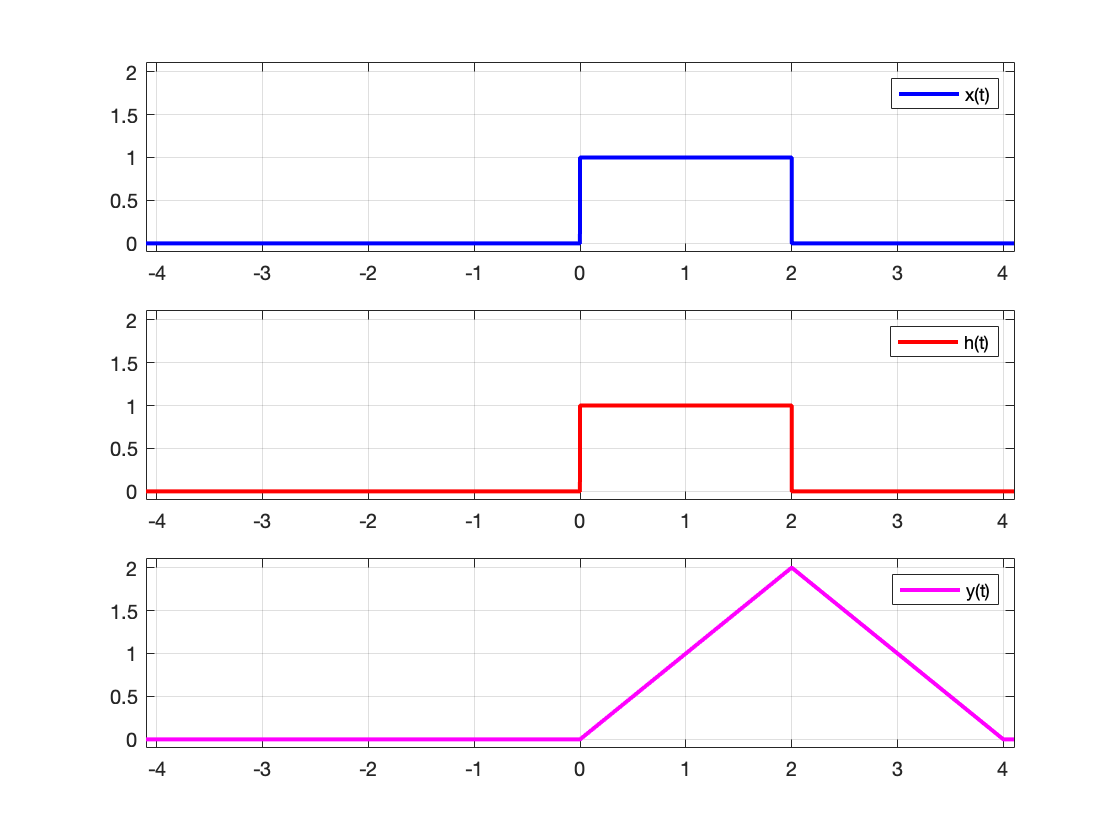

ylim([-0.1 (bval-aval)+0.1]);
xlim([-xmax xmax])

nexttile;
fplot(yp,'m','LineWidth',2)
grid on;
legend('y(t)');
ylim([-0.1 (bval-aval)+0.1]);
xlim([-xmax xmax])

# Approfondissement : comparaison avec l'autocorrélation

close all;
clearvars;
syms u t a b
assume(a<b)
sig1= @(t) rectangularPulse(a,b,t)

sig1 = function_handle with value:
    @(t)rectangularPulse(a,b,t)


## Calcul de l'autocorrelation 


$$R_{xx}\left ( \tau \right )=\int_{-\infty}^{+\infty}x\left ( t \right )x\left ( t- \tau \right )dt = x(t)*x(-t)$$
    

figure;
tiledlayout(1,1)
nexttile;% Calcul del'intercorrelation Ryx
x=sig1(t) 

$$x = \mathrm{rectangularPulse}\left(a,b,t\right)$$

y(t)=sig1(-t)

$$y(t) = \mathrm{rectangularPulse}\left(a,b,-t\right)$$

yc=y(u-t)

$$yc = \mathrm{rectangularPulse}\left(a,b,t-u\right)$$

disp('Expression litterale de Rxy')

Expression litterale de Rxy


%Rxy= int(x*yc, t, -2*(b-a),2*(b-a));
Rxy1= int(x*yc, t, -20,20);
Rxy1 = simplify(Rxy1 ,'Steps',50)

Assignation de valeurs pour a et b pour le tracé de l'autocorrelation

aval=0 

aval = 0

bval=2

bval = 2


xp=subs(x,[a, b],[aval, bval])

$$xp = \mathrm{rectangularPulse}\left(0,2,t\right)$$

Rxy1p=subs(Rxy1,[a, b],[aval, bval])

$$Rxy1p = \left\{ \begin{array}{cl} 2 & \text{ if }u=0\\ 0 & \text{ if }2\leq u\vee u\leq -2\\ 2-u & \text{ if }u\in \left[0,2\right]\\ u+2 & \text{ if }u\in \left[-2,0\right] \end{array}\right.$$



xlim([-10 10]);
ax = gca;
S = sym(ax.XLim(1):1:ax.XLim(2));       % graduation pour fonction classique
%S = sym(ax.XLim(1):pi:ax.XLim(2));     % graduation pour fonction trigo
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);
grid on;
hold on;
fplot(Rxy1p,'c','LineWidth',2)
ylim([-1 2.1]);
xmax=2*(bval-aval)+0.1

xmax = 4.1000

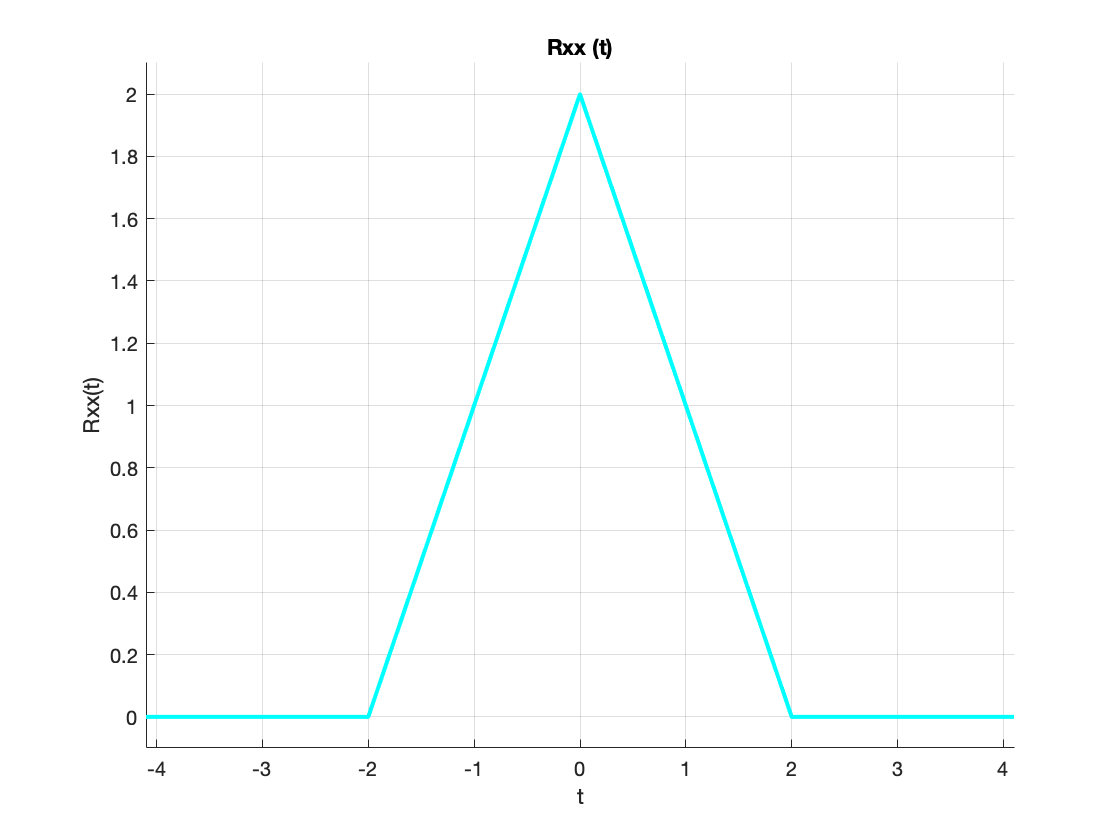

ylim([-0.1 (bval-aval)+0.1]);
xlim([-xmax xmax])
%legend;
xlabel('t');
ylabel('Rxx(t)');
title('Rxx (t)');


$$R_{xx}\left ( \tau \right )=\int_{-\infty}^{+\infty}x\left ( t \right )x\left ( t- \tau \right )dt = x(t)*x(-t)$$


% autre méthode pour l'autocorrelation

figure;
tiledlayout(1,1)
nexttile;% Calcul del'intercorrelation Ryx
x=sig1(t) 

$$x = \mathrm{rectangularPulse}\left(a,b,t\right)$$

y(t)=sig1(t)

$$y(t) = \mathrm{rectangularPulse}\left(a,b,t\right)$$

yc=y(t-u)

$$yc = \mathrm{rectangularPulse}\left(a,b,t-u\right)$$

disp('Expression litterale de Rxy')

Expression litterale de Rxy


%Rxy= int(x*yc, t, -2*(b-a),2*(b-a));
Rxy2= int(x*yc, t, -20,20);
Rxy2 = simplify(Rxy2 ,'Steps',50)

Assignation de valeurs pour a et b pour le tracé de l'autocorrelation

aval=0 

aval = 0

bval=2

bval = 2

xp=subs(x,[a, b],[aval, bval])

$$xp = \mathrm{rectangularPulse}\left(0,2,t\right)$$

Rxy2p=subs(Rxy2,[a, b],[aval, bval])

$$Rxy2p = \left\{ \begin{array}{cl} 2 & \text{ if }u=0\\ 0 & \text{ if }2\leq u\vee u\leq -2\\ 2-u & \text{ if }u\in \left[0,2\right]\\ u+2 & \text{ if }u\in \left[-2,0\right] \end{array}\right.$$



xlim([-10 10]);
ax = gca;
S = sym(ax.XLim(1):1:ax.XLim(2));       % graduation pour fonction classique
%S = sym(ax.XLim(1):pi:ax.XLim(2));     % graduation pour fonction trigo
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);
grid on;
hold on;
fplot(Rxy2p,'m','LineWidth',2)
ylim([-1 2.1]);
xmax=2*(bval-aval)+0.1

xmax = 4.1000

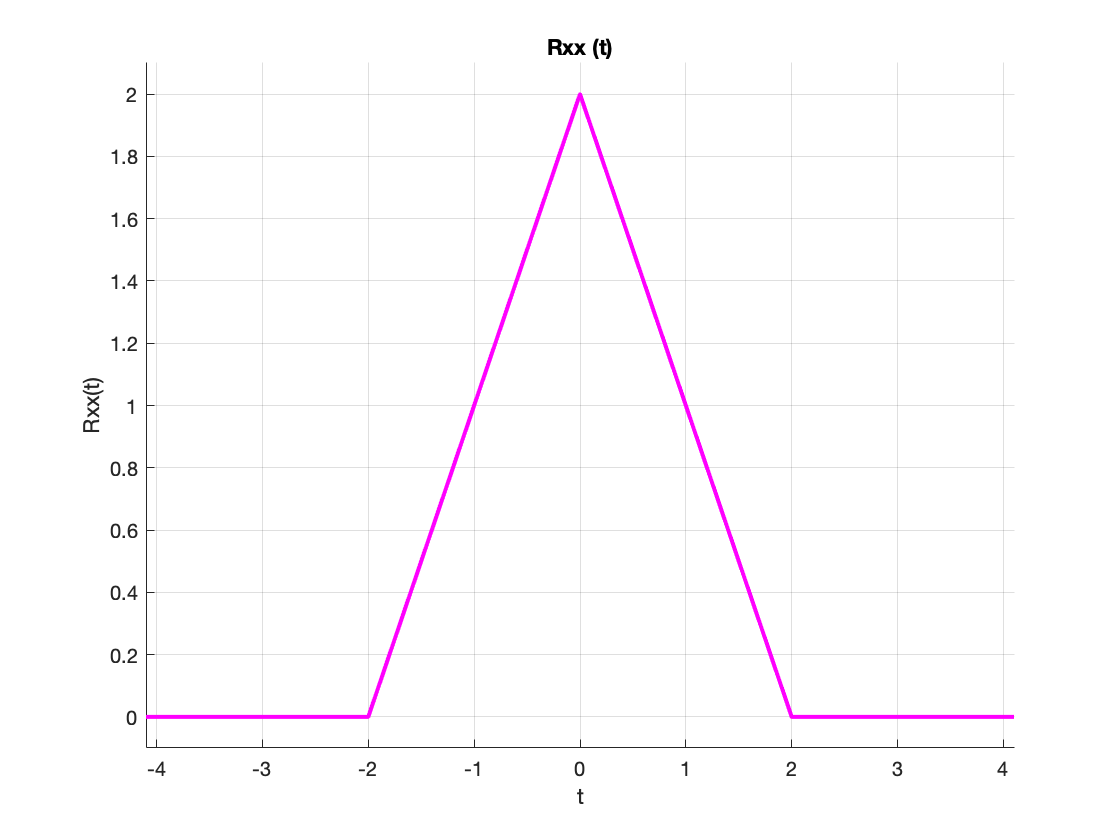

ylim([-0.1 (bval-aval)+0.1]);
xlim([-xmax xmax])
%legend;
xlabel('t');
ylabel('Rxx(t)');
title('Rxx (t)');